# Interactive MATLAB Lab 1.6: Autonomous and Nonautonomous Direction-Field Explorer

In a Live Script, turn "type" into a drop-down control and K into a slider.

type = "Autonomous";   % Options: "Autonomous", "Nonautonomous"
K = 6;

if type == "Autonomous"
    xValues = linspace(0,8,25);
    yValues = linspace(-2,K+4,25);
    [X,Y] = meshgrid(xValues,yValues);

    U = ones(size(X));
    V = Y.*(1-Y./K);

    description = "The slope depends only on y; x does not appear explicitly.";
    equationText = "y' = y(1-y/K)";
else
    xValues = linspace(0,8,25);
    yValues = linspace(-6,6,25);
    [X,Y] = meshgrid(xValues,yValues);

    U = ones(size(X));
    V = Y.*cos(X);

    description = "The slope depends explicitly on x, so the equation is nonautonomous.";
    equationText = "y' = y cos(x)";
end

arrowLength = sqrt(U.^2 + V.^2);
U = U./arrowLength;
V = V./arrowLength;

disp("Differential equation: " + equationText)

Differential equation: y' = y(1-y/K)


disp("Classification: " + type)

Classification: Autonomous


disp(description)

The slope depends only on y; x does not appear explicitly.


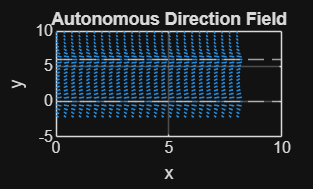

Equilibrium values: 0 and 6



figure
quiver(X,Y,U,V,0.45)
grid on
xlabel('x')
ylabel('y')

if type == "Autonomous"
    hold on
    yline(0,'--')
    yline(K,'--')
    hold off
    title('Autonomous Direction Field')
    disp("Equilibrium values: 0 and " + string(K))
else
    title('Nonautonomous Direction Field')
end